## LABORATORIO 2 

## FUNDAMENTOS DE ROBÓTICA INDUSTRIAL

### Natalia Tello, Julián Villanueva

### Universidad Nacional de Colombia

- **Objetivos** 

-Hacer una introducción al manejo de la herramienta MATLAB® para la simulación de robots. 

-Simular el comportamiento del robot industrial (asignado a su grupo) teniendo en cuenta sus características y haciendo uso de los toolboxes RVCtools de Peter Corke y Robotics System Toolbox (RST) de MATLAB®.

-Construir los modelos cinem´aticos directo, inverso y diferencial de un robot Industrial.

-Generar rutas y trayectorias y simular el seguimiento de las trayectorias.

-Implementar una GUI en MATLAB® para demostrar el funcionamiento de los modelos.

## Características y modelo del robot

1. Imagen del robot.

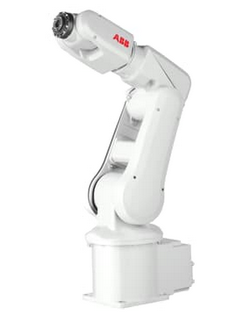

2. Capacidad de carga.

3. Alcance vertical y horizontal.

4. Repetibilidad.

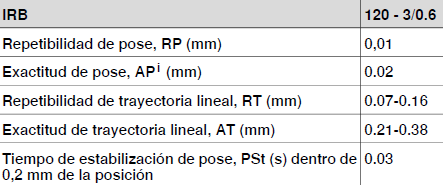

5. Gráfica(s) de espacio alcanzable.

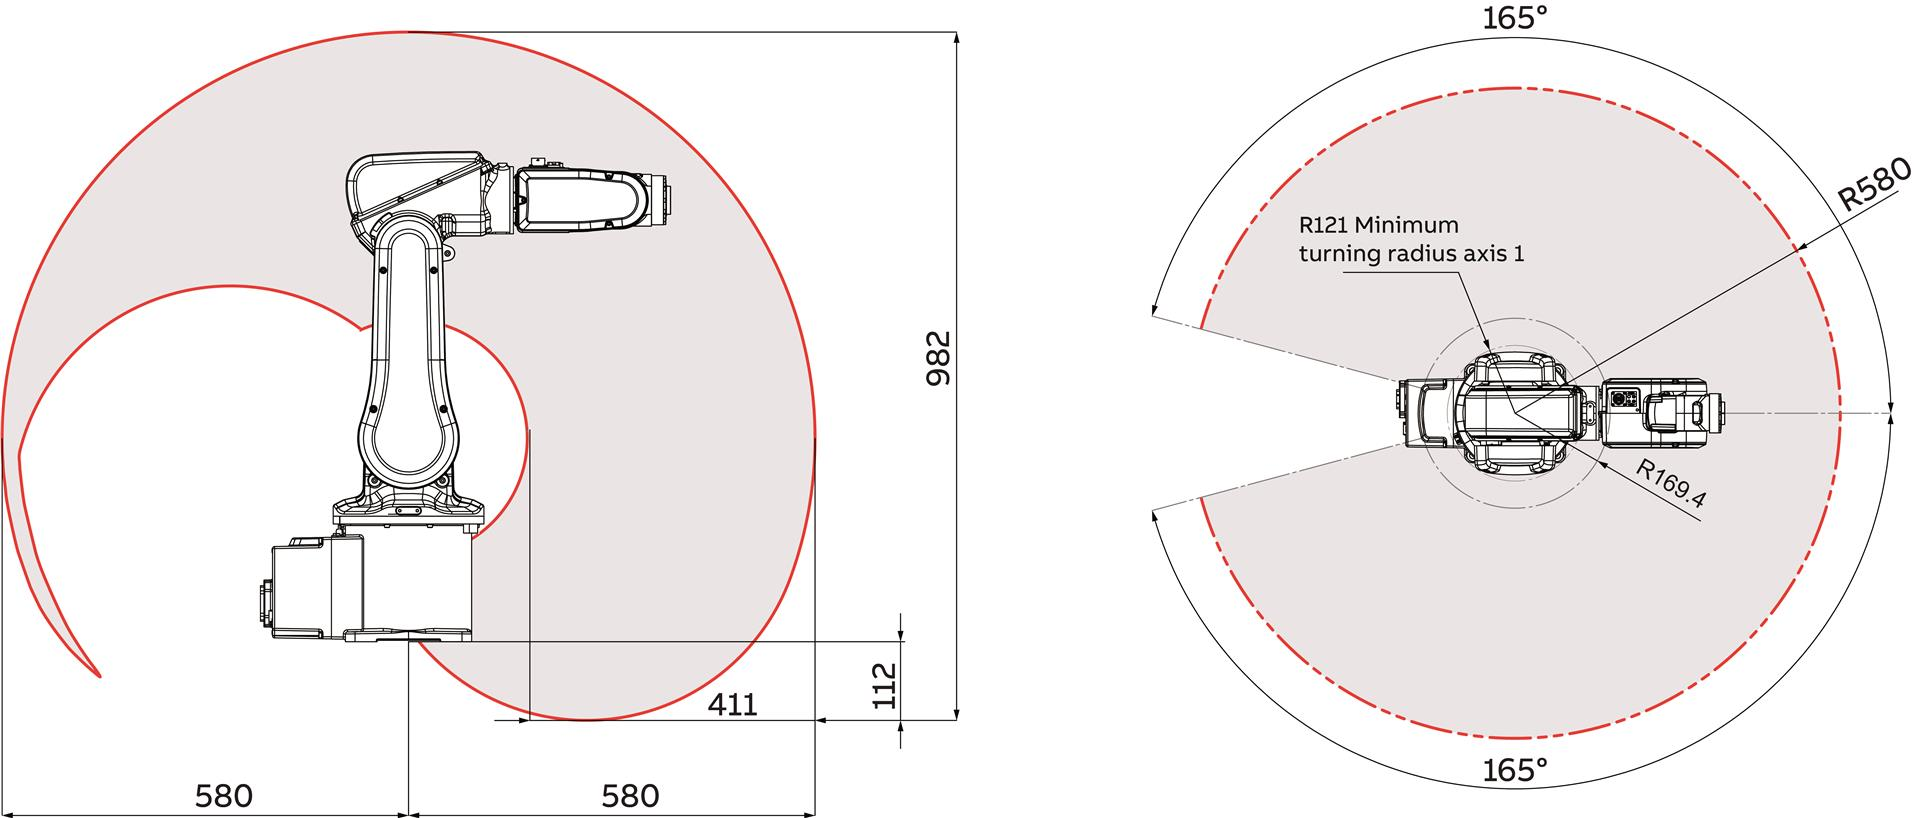

6. Tabla de parámetros DH.

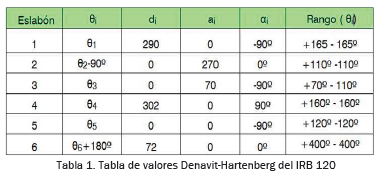

7. Qué software utiliza el fabricante para diseño de celdas o programación.

"***RobotStudio*** es el software de simulación y programación offline de ABB,  que ofrece una réplica digital completa (Digital Twin) de activos o  sistemas físicos para que pueda ver lo que sucede en su línea de  producción de forma remota...Esta herramienta permite a los usuaros crear, simular y probar  una instalación completa de robot en un entorno virtual 3D sin tener que visitar o perturbar su línea de producción real". Tomado de: [https://new.abb.com/products/robotics/es/robotstudio/descargas](https://new.abb.com/products/robotics/es/robotstudio/descargas) 

- Halle el modelo geométrico directo de su robot asignado usando MTH.

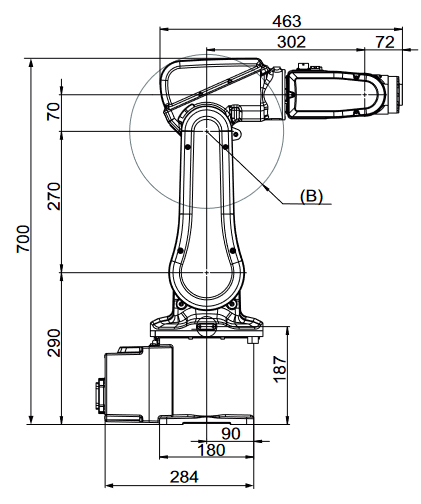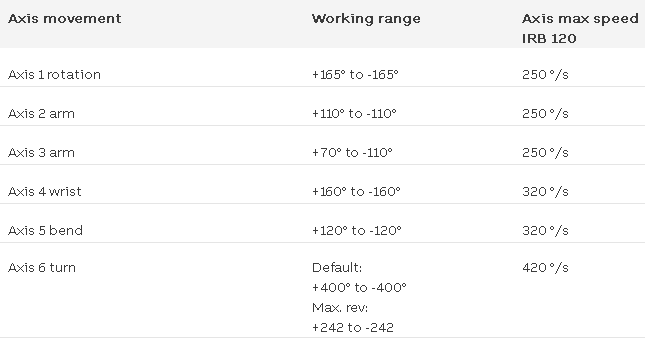

startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for Matlab (release 9.10)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2021) (c)
** Release <!DOCTYPE HTML PUBLIC "-//IETF//DTD HTML 2.0//EN">
<html><head>
<title>301 Moved Permanently</title>
</head><body>
<h1>Moved Permanently</h1>
<p>The document has moved <a href="https://www.petercorke.com/RTB/currentversion.php">here</a>.</p>
</body></html>
 now available

Run rtbdemo to explore the toolbox


Puesto que el robot IRB120 no se encuentra en los modelos de peter Corke es necesario crear los eslabones y articulaciones correspondientes usando la convención de DH modificada de la siguiente forma:

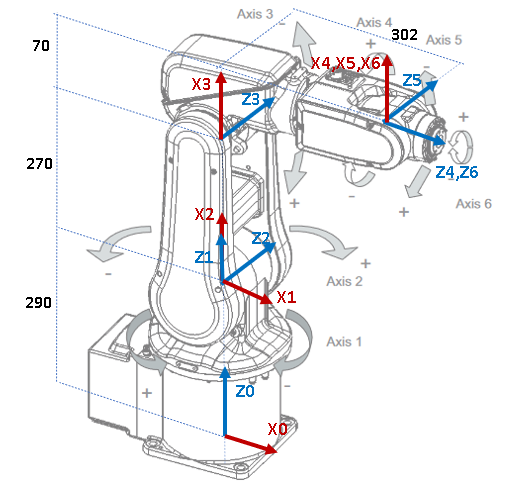

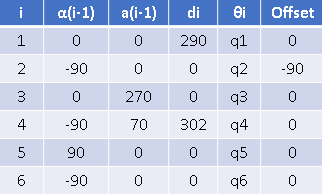

ws=[-1 1 -1 1 -1 1];
plot_options = {'workspace',ws,'scale',0.5,'view',[-25 150], 'tilesize',2,  'ortho',...
    'lightpos',[2 2 10] };

L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,  'd',   0.290 , 'offset',   0,...
    'qlim',  [-11*pi/12 11*pi/12],   'modified');
L(2) = Link('revolute'   ,'alpha',   -pi/2,  'a',  0,  'd',   0    , 'offset',   -pi/2,...
    'qlim',  [-11*pi/18 11*pi/18],   'modified');
L(3) = Link('revolute'  ,'alpha',      0,  'a', 0.27,  'd',   0    , 'offset',   0,...
    'qlim',  [-11*pi/18 7*pi/18],   'modified');
L(4) = Link('revolute'   ,'alpha',  -pi/2,  'a',0.07,  'd',  0.302 , 'offset',   0,...
    'qlim',  [-8*pi/9 8*pi/9],   'modified');
L(5) = Link('revolute'   ,'alpha',   pi/2,  'a',  0,  'd',    0    , 'offset',   0,...
    'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,  'd',    0    , 'offset',   0,...
    'qlim',  [-20*pi/9 20*pi/9],   'modified');

IRB120= SerialLink(L,'name', 'IRB 120')

 
IRB120 = 
 
IRB 120 (6 axis, RRRRRR, modDH, fastRNE)                         
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.29|          0|          0|          0|
|  2|         q2|          0|          0|     -1.571|     -1.571|
|  3|         q3|          0|       0.27|          0|          0|
|  4|         q4|      0.302|       0.07|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|          0|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0           

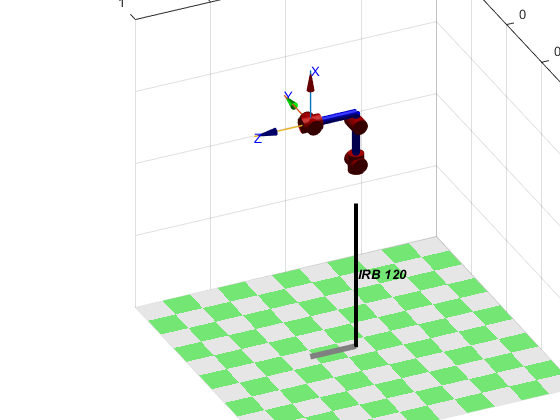

    
 q=[0 0 0 0 0 0];
 IRB120.teach(q);
 IRB120.plot(q,'workspace', ws, 'tilesize', 0.5,'view',[-25 150])

2. Considerando el robot asignado, construya el modelo del robot utilizando RST.

body1 = rigidBody('body1'); 
jnt1 = rigidBodyJoint('jnt1','revolute'); 
jnt1.HomePosition = 0; 
tform = trvec2tform([0, 0, 0]); 
setFixedTransform(jnt1,tform); 
body1.Joint = jnt1;

robot = rigidBodyTree;

addBody(robot,body1,'base')
body2 = rigidBody('body2'); 
jnt2 = rigidBodyJoint('jnt2','revolute'); 
jnt2.HomePosition = 0; 
tform2 = trvec2tform([0, 0, 0.29]); 
setFixedTransform(jnt2,tform2); 
body2.Joint = jnt2; 
addBody(robot,body2,'body1'); % Add body2 to body1

body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6');
body7 = rigidBody('body7'); 

jnt3 = rigidBodyJoint('jnt3','revolute'); 
jnt4 = rigidBodyJoint('jnt4','revolute'); 
jnt5 = rigidBodyJoint('jnt5','revolute'); 
jnt6 = rigidBodyJoint('jnt6','revolute'); 
jnt7 = rigidBodyJoint('jnt7','revolute'); 

tform3 = trvec2tform([0, 0, 0])*eul2tform([-pi/2, -pi/2, 0]); 
tform4 = trvec2tform([0.27, 0, 0]); 
tform5 = trvec2tform([0.07, 0.302, 0])*eul2tform([0, 0, -pi/2]);
tform6 = trvec2tform([0, 0, 0])*eul2tform([0, 0, pi/2]);
tform7 = trvec2tform([0, 0, 0])*eul2tform([0, 0, -pi/2]);


setFixedTransform(jnt3,tform3); 
setFixedTransform(jnt4,tform4);
setFixedTransform(jnt5,tform5);
setFixedTransform(jnt6,tform6);
setFixedTransform(jnt7,tform7);

jnt3.HomePosition = 0;
jnt4.HomePosition = 0;
jnt5.HomePosition = 0;
jnt6.HomePosition = 0;
jnt7.HomePosition = 0;

body3.Joint = jnt3 

body3 =   rigidBody with properties:

            Name: 'body3'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


body4.Joint = jnt4 

body4 =   rigidBody with properties:

            Name: 'body4'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


body5.Joint = jnt5

body5 =   rigidBody with properties:

            Name: 'body5'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


body6.Joint = jnt6

body6 =   rigidBody with properties:

            Name: 'body6'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


body7.Joint = jnt7

body7 =   rigidBody with properties:

            Name: 'body7'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


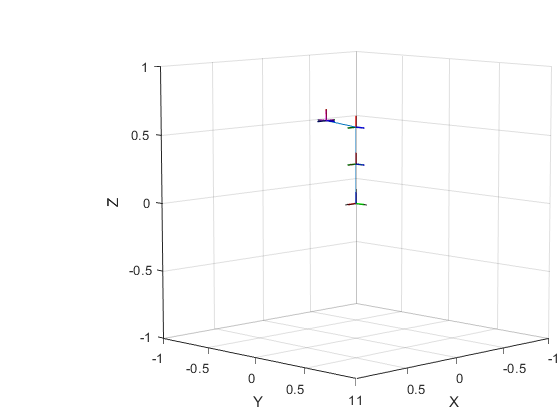

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [190.9600 46.2000 331.8000 342.3000]
            Units: 'pixels'

  Show all properties



addBody(robot,body3,'body2'); 
addBody(robot,body4,'body3'); 
addBody(robot,body5,'body4'); 
addBody(robot,body6,'body5'); 
addBody(robot,body7,'body6'); 

bodyEndEffector = rigidBody('endeffector'); 
tform8 = trvec2tform([0, 0, 0])*eul2tform([0, 0, 0]);
setFixedTransform(bodyEndEffector.Joint,tform7); 
addBody(robot,bodyEndEffector,'body7');

show(robot)

%%%%%tambien se puede cargar un robot de la liberia 
 
irb_120=loadrobot("abbIrb120");

irb_120

irb_120 =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'link_1'  'link_2'  'link_3'  'link_4'  'link_5'  'link_6'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


figure(5)
show(irb_120)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


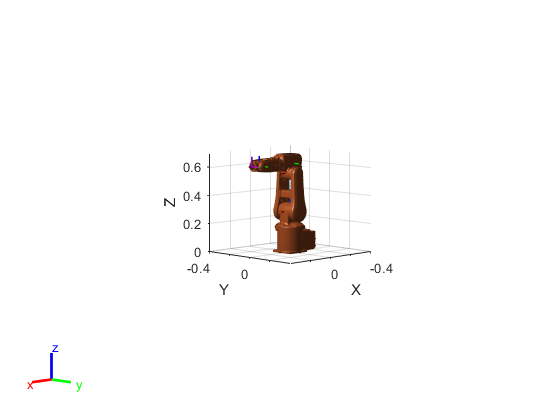

xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.7]);

3. Compare los dos métodos.

Usando RVC es posible crear cualquier robot teniendo la tabla de parámetros DH estandar o modificados, mientras que en RST crear cualquier robot es mucho más complejo pues deben crearse cuerpos rígidos, y la relación de desplzamiento y orientación entre cada una de las tramas, sin embargo en este caso ya se encuentra cargado el modelo del robot IRB120 y solo fue cargarlo al espacio de trabajo mediando el comando loadrobot.

4. Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

A continuación se presentan los puntos de calibración:

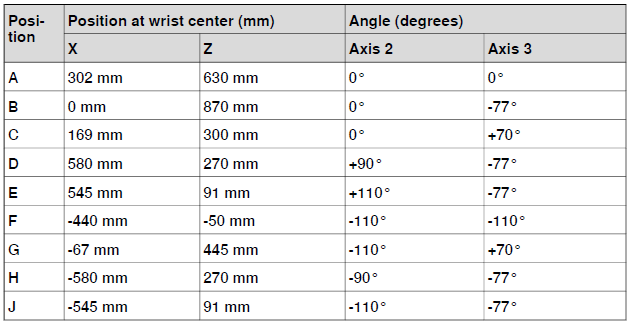

%%%%%%ingresamos configuraciones articulares
q_a=[0 0 0 0 0 0];
q_b=[0 0 (-77*pi/180) 0 0 0];
q_c=[0 0 (70*pi/180) 0 0 0];
q_d=[0 (90*pi/180) (-77*pi/180) 0 0 0];
q_e=[0 (110*pi/180) (-77*pi/180) 0 0 0];
q_f=[0 (-110*pi/180) (-110*pi/180) 0 0 0];
q_g=[0 (-110*pi/180) (70*pi/180) 0 0 0];
q_h=[0 (-90*pi/180) (-77*pi/180) 0 0 0];
q_j=[0 (-110*pi/180) (-77*pi/180) 0 0 0];
%%%%%%Cinematica directa para cada configuracion
TCPA=IRB120.fkine(q_a);
TCPB=IRB120.fkine(q_b);
TCPC=IRB120.fkine(q_c);
TCPD=IRB120.fkine(q_d);
TCPE=IRB120.fkine(q_e);
TCPF=IRB120.fkine(q_f);
TCPG=IRB120.fkine(q_g);
TCPH=IRB120.fkine(q_h);
TCPJ=IRB120.fkine(q_j);

%%%%%%Extraemos posiciones X y Z,x1000 para medida en mm
A=[TCPA(1,4)*1000,TCPA(3,4)*1000]

A =    302   630


B=[TCPB(1,4)*1000,TCPB(3,4)*1000]

B =    -0.2707  870.0063


C=[TCPC(1,4)*1000,TCPC(3,4)*1000]

C =   169.0686  300.1542


D=[TCPD(1,4)*1000,TCPD(3,4)*1000]

D =   580.0063  290.2707


E=[TCPE(1,4)*1000,TCPE(3,4)*1000]

E =   545.1203   91.8805


F=[TCPF(1,4)*1000,TCPF(3,4)*1000]

F =  -440.0673  -50.0904


G=[TCPG(1,4)*1000,TCPG(3,4)*1000]

G =   -67.3667  445.3995


H=[TCPH(1,4)*1000,TCPH(3,4)*1000]

H =  -580.0063  289.7293


J=[TCPJ(1,4)*1000,TCPJ(3,4)*1000]

J =  -544.9351   91.3718


Se cumplen los puntos en su mayoría, se encuentra una pequeña desviación de 20mm en los puntos D y H, sin embargo puede deberse a la cantidad de decimales que toma matlab en las configuraciones articulares.

## Modelo Geometrico Directo

1. Halle el modelo geométrico directo de su robot asignado usando MTH.

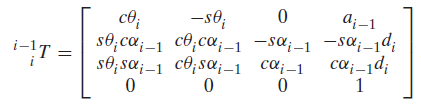

Tambien debe agregarse el desplazamiento en Z de la muñeca a la conexión del tool de 72mm puede hacerce con una matriz de transformación, tambien conserva el mismo marco de la base

%%%%%%%% ESLABON 1
syms q1 q2 q3 q4 q5 q6 real
alpha_0=0;
a_0=0;
d_1=0.29;
theta_1=q1;
F_1=[cos(theta_1),-sin(theta_1),0,a_0;
    sin(theta_1)*cos(alpha_0),cos(theta_1)*cos(alpha_0),-sin(alpha_0),-sin(alpha_0)*d_1;
    sin(theta_1)*sin(alpha_0),cos(theta_1)*sin(alpha_0),cos(alpha_0),cos(alpha_0)*d_1;
    0,0,0,1];

%%%%%%%% ESLABON 2
alpha_1=-pi/2;
a_1=0;
d_2=0;
theta_2=(q2-pi/2);

F_2=Tsimple([cos(theta_2),-sin(theta_2),0,a_1;
    sin(theta_2)*cos(alpha_1),cos(theta_2)*cos(alpha_1),-sin(alpha_1),-sin(alpha_1)*d_2;
    sin(theta_2)*sin(alpha_1),cos(theta_2)*sin(alpha_1),cos(alpha_1),cos(alpha_1)*d_2;
    0,0,0,1]);
%%%%%%%% ESLABON 3
alpha_2=0;
a_2=0.270;
d_3=0;
theta_3=q3;

F_3=Tsimple([cos(theta_3),-sin(theta_3),0,a_2;
    sin(theta_3)*cos(alpha_2),cos(theta_3)*cos(alpha_2),-sin(alpha_2),-sin(alpha_2)*d_3;
    sin(theta_3)*sin(alpha_2),cos(theta_3)*sin(alpha_2),cos(alpha_2),cos(alpha_2)*d_3;
    0,0,0,1]);
%%%%%%%% ESLABON 4
alpha_3=-pi/2;
a_3=0.07;
d_4=0.302;
theta_4=q4;

F_4=Tsimple([cos(theta_4),-sin(theta_4),0,a_3;
    sin(theta_4)*cos(alpha_3),cos(theta_4)*cos(alpha_3),-sin(alpha_3),-sin(alpha_3)*d_4;
    sin(theta_4)*sin(alpha_3),cos(theta_4)*sin(alpha_3),cos(alpha_3),cos(alpha_3)*d_4;
    0,0,0,1]);
%%%%%%%% ESLABON 5
alpha_4=pi/2;
a_4=0;
d_5=0;
theta_5=q5;

F_5=Tsimple([cos(theta_5),-sin(theta_5),0,a_4;
    sin(theta_5)*cos(alpha_4),cos(theta_5)*cos(alpha_4),-sin(alpha_4),-sin(alpha_4)*d_5;
    sin(theta_5)*sin(alpha_4),cos(theta_5)*sin(alpha_4),cos(alpha_4),cos(alpha_4)*d_5;
    0,0,0,1]);

%%%%%%%% ESLABON 6
alpha_5=-pi/2;
a_5=0;
d_6=0;
theta_6=q6;

F_6=Tsimple([cos(theta_6),-sin(theta_6),0,a_5;
    sin(theta_6)*cos(alpha_5),cos(theta_6)*cos(alpha_5),-sin(alpha_5),-sin(alpha_5)*d_6;
    sin(theta_6)*sin(alpha_5),cos(theta_6)*sin(alpha_5),cos(alpha_5),cos(alpha_5)*d_6;
    0,0,0,1]);

%%%%%%% Tool
F_7=[0 0 1 0;
    0 -1 0 0;
    1 0 0 0.072;
    0 0 0 1]

F_7 =          0         0    1.0000         0
         0   -1.0000         0         0
    1.0000         0         0    0.0720
         0         0         0    1.0000



%%%%%%% MTH
MTH=F_1*F_2*F_3*F_4*F_5*F_6*F_7;



Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares:

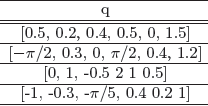

%%%%% Verificamos inicialmente posicion de HOME
Q_0 = [0 0 0 0 0 0];
q1=Q_0(1);
q2=Q_0(2);
q3=Q_0(3);
q4=Q_0(4);
q5=Q_0(5);
q6=Q_0(6);
MTH1= eval(MTH)

MTH1 =     1.0000         0    0.0000    0.3740
         0    1.0000         0         0
   -0.0000         0    1.0000    0.6300
         0         0         0    1.0000


P1=[MTH1(1:3,4)]'%%%%%posicion x y z

P1 =     0.3740         0    0.6300


betha_1=asin(-MTH1(3,1));%%%pitch
gamma_1=asin(MTH1(3,2)/cos(betha_1));%%%%roll
alfa_1=acos(MTH1(1,1)/cos(betha_1));%%%yaw
O1=[gamma_1,betha_1,alfa_1]

O1 = 	1.0e+-16 *

         0    0.6123         0



%%%%% PUNTO 1
Q_1 = [0.5 0.2 0.4 0.5 0 1.5];
q1=Q_1(1);
q2=Q_1(2);
q3=Q_1(3);
q4=Q_1(4);
q5=Q_1(5);
q6=Q_1(6);
MTH1= eval(MTH)

MTH1 =     0.7243    0.6501    0.2297    0.3526
    0.3957   -0.1191   -0.9106    0.1927
   -0.5646    0.7505   -0.3435    0.4012
         0         0         0    1.0000


P1=[MTH1(1:3,4)]'%%%%%posicion x y z

P1 =     0.3526    0.1927    0.4012


betha_1=asin(-MTH1(3,1));%%%pitch
gamma_1=asin(MTH1(3,2)/cos(betha_1));%%%%roll
alfa_1=acos(MTH1(1,1)/cos(betha_1));%%%yaw
O1=[gamma_1,betha_1,alfa_1]

O1 =     1.1416    0.6000    0.5000




%%%%% PUNTO 2
Q_2 = [-pi/2 0.3 0 pi/2 0.4 1.2];
q1=Q_2(1);
q2=Q_2(2);
q3=Q_2(3);
q4=Q_2(4);
q5=Q_2(5);
q6=Q_2(6);
MTH2= eval(MTH)

MTH2 =     0.3894   -0.8585   -0.3338    0.0280
   -0.8799   -0.4538    0.1406   -0.4523
   -0.2722    0.2389   -0.9321    0.5060
         0         0         0    1.0000


P2=[MTH2(1:3,4)]'%%%%%posicion x y z

P2 =     0.0280   -0.4523    0.5060


betha_2=asin(-MTH2(3,1));%%%pitch
gamma_2=asin(MTH2(3,2)/cos(betha_2));%%%%roll
alfa_2=acos(MTH2(1,1)/cos(betha_2));%%%yaw
O2=[gamma_2,betha_2,alfa_2]

O2 =     0.2509    0.2757    1.1541




%%%%% PUNTO 3
Q_3 = [0 1 -0.5 2 1 0.5];
q1=Q_3(1);
q2=Q_3(2);
q3=Q_3(3);
q4=Q_3(4);
q5=Q_3(5);
q6=Q_3(6);
MTH3= eval(MTH)

MTH3 =     0.6420    0.6849    0.3445    0.5720
    0.7651   -0.6007   -0.2316    0.0551
    0.0483    0.4123   -0.9098    0.3560
         0         0         0    1.0000


P3=[MTH3(1:3,4)]'%%%%%posicion x y z

P3 =     0.5720    0.0551    0.3560


betha_3=asin(-MTH3(3,1));%%%pitch
gamma_3=asin(MTH3(3,2)/cos(betha_3));%%%%roll
alfa_3=acos(MTH3(1,1)/cos(betha_3));%%%yaw
O3=[gamma_3,betha_3,alfa_3]%%%%%% orientación rpy

O3 =     0.4255   -0.0483    0.8727




%%%%% PUNTO 4
Q_4 = [-1 -0.3 -pi/5 0.4 0.2 1];
q1=Q_4(1);
q2=Q_4(2);
q3=Q_4(3);
q4=Q_4(4);
q5=Q_4(5);
q6=Q_4(6);
MTH4= eval(MTH)

MTH4 =     0.4615   -0.2170   -0.8602    0.0576
   -0.5756    0.6646   -0.4765   -0.0794
    0.6750    0.7150    0.1818    0.8803
         0         0         0    1.0000



P4=[MTH4(1:3,4)]'%%%%%posicion x y z

P4 =     0.0576   -0.0794    0.8803


betha_4=asin(-MTH4(3,1));%%%pitch
gamma_4=asin(MTH4(3,2)/cos(betha_4));%%%%roll
alfa_4=acos(MTH4(1,1)/cos(betha_4));%%%yaw
O4=[gamma_4,betha_4,alfa_4]%%%%%% orientación rpy

O4 =     1.3218   -0.7410    0.8949


Finalmente se obtiene la tabla:

Configuracion = {'[0.5, 0.2, 0.4, 0.5, 0, 1.5]';
    '[pi/2 0.3 0 pi/2 0.4 1.2]';
    '[0 1 -0.5 2 1 0.5]';
    '[-1 -0.3 -pi/5 0.4 0.2 1]'};
Posicion = [P1; P2; P3; P4];
Orientacion = [O1; O2; O3; O4];
%Ta = table(Configuracion,Posicion,Orientacion);

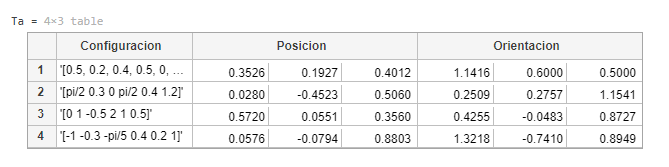

3. Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

Es necesario agregar al robot anterior, un desplazamiento en el eje Z que represeta la distancia entre la muñeca y el efector final, en este caso de 72 mm y luego se aplica la funcion fkine para cinematica directa del toolbox

IRB120.tool=transl(0,0,0.072)*troty(pi/2)*trotz(pi)

 
IRB120 = 
 
IRB 120 (6 axis, RRRRRR, modDH, fastRNE)                                      
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|       0.29|          0|          0|          0|             
|  2|         q2|          0|          0|     -1.571|     -1.571|             
|  3|         q3|          0|       0.27|          0|          0|             
|  4|         q4|      0.302|       0.07|     -1.571|          0|             
|  5|         q5|          0|          0|      1.571|          0|             
|  6|         q6|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                      

%%%%%Toolbox RVC
MTH0_RVC=IRB120.fkine(q)

MTH0_RVC =     1.0000    0.0000    0.0000    0.3740
   -0.0000    1.0000   -0.0000    0.0000
   -0.0000    0.0000    1.0000    0.6300
         0         0         0    1.0000


MTH1_RVC=IRB120.fkine(Q_1)

MTH1_RVC =     0.7243    0.6501    0.2297    0.3526
    0.3957   -0.1191   -0.9106    0.1927
   -0.5646    0.7505   -0.3435    0.4012
         0         0         0    1.0000


MTH2_RVC=IRB120.fkine(Q_2)

MTH2_RVC =     0.3894   -0.8585   -0.3338    0.0280
   -0.8799   -0.4538    0.1406   -0.4523
   -0.2722    0.2389   -0.9321    0.5060
         0         0         0    1.0000


MTH3_RVC=IRB120.fkine(Q_3)

MTH3_RVC =     0.6420    0.6849    0.3445    0.5720
    0.7651   -0.6007   -0.2316    0.0551
    0.0483    0.4123   -0.9098    0.3560
         0         0         0    1.0000


MTH4_RVC=IRB120.fkine(Q_4)

MTH4_RVC =     0.4615   -0.2170   -0.8602    0.0576
   -0.5756    0.6646   -0.4765   -0.0794
    0.6750    0.7150    0.1818    0.8803
         0         0         0    1.0000


%%%%%Toolbox RST
configuracion0=homeConfiguration(irb_120);
MTH0_RST = getTransform(irb_120,configuracion0,'base','tool0')

MTH0_RST =     1.0000         0         0   -0.3740
         0    1.0000         0         0
         0         0    1.0000   -0.6300
         0         0         0    1.0000


configuracion1=homeConfiguration(irb_120);
configuracion1(1).JointPosition = 0.5;
configuracion1(2).JointPosition = 0.2;
configuracion1(3).JointPosition = 0.4;
configuracion1(4).JointPosition = 0.5;
configuracion1(5).JointPosition = 0;
configuracion1(6).JointPosition = 1.5;
MTH1_RST = getTransform(irb_120,configuracion1,'base','tool0')

MTH1_RST =     0.7243    0.3957   -0.5646   -0.1051
    0.6501   -0.1191    0.7505   -0.5074
    0.2297   -0.9106   -0.3435    0.2322
         0         0         0    1.0000


configuracion2=homeConfiguration(irb_120);
configuracion2(1).JointPosition = -pi/2;
configuracion2(2).JointPosition = 0.3;
configuracion2(3).JointPosition = 0;
configuracion2(4).JointPosition = pi/2;
configuracion2(5).JointPosition = 0.4;
configuracion2(6).JointPosition = 1.2;
MTH2_RST = getTransform(irb_120,configuracion2,'base','tool0')

MTH2_RST =     0.3894   -0.8799   -0.2722   -0.2712
   -0.8585   -0.4538    0.2389   -0.3021
   -0.3338    0.1406   -0.9321    0.5446
         0         0         0    1.0000


configuracion3=homeConfiguration(irb_120);
configuracion3(1).JointPosition = 0;
configuracion3(2).JointPosition = 1;
configuracion3(3).JointPosition = -0.5;
configuracion3(4).JointPosition = 2;
configuracion3(5).JointPosition = 1;
configuracion3(6).JointPosition = 0.5;
MTH3_RST = getTransform(irb_120,configuracion3,'base','tool0')

MTH3_RST =     0.6420    0.7651    0.0483   -0.4266
    0.6849   -0.6007    0.4123   -0.5055
    0.3445   -0.2316   -0.9098    0.1396
         0         0         0    1.0000


configuracion4=homeConfiguration(irb_120);
configuracion4(1).JointPosition = -1;
configuracion4(2).JointPosition = -0.3;
configuracion4(3).JointPosition = -pi/5;
configuracion4(4).JointPosition = 0.4;
configuracion4(5).JointPosition = 0.2;
configuracion4(6).JointPosition = 1;
MTH4_RST = getTransform(irb_120,configuracion4,'base','tool0')

MTH4_RST =     0.4615   -0.5756    0.6750   -0.6665
   -0.2170    0.6646    0.7150   -0.5642
   -0.8602   -0.4765    0.1818   -0.1483
         0         0         0    1.0000


4. Compare los métodos.

Con el Toolbox de RST no se obtienen los mismos resultados, esto se debe a que el robot no cuenta con la misma asignación de ejes 

Home_RST = getTransform(irb_120,homeConfiguration(irb_120),'base','link_6')

Home_RST =     1.0000         0         0   -0.3740
         0    1.0000         0         0
         0         0    1.0000   -0.6300
         0         0         0    1.0000


Se puede ver que la posición en X y Z para la posición de home del robot son negativas, lo cual no coincide visualmente con la realidad.

5. Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

Se realiza una gui con sliders para cada articulación, que muestre el valor exacto del slider a la derecha y que tenga un boton para graficar. Se realiza un callback de cada slicer de manera que se pueda abstraer el valor e ingresarlo en una propiedad ya que solo mediante propiedades se comunican los diferentes objetos

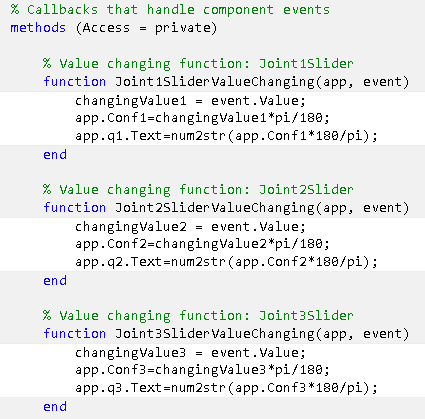

Se realiza de igual forma para los slicers 4, 5 y 6.

Por ultimo se realiza el callback del boton de graficar donde se crea el robot y se introduce el comando TEACH del toolbox de Peter Corke para graficar tanto el robot como la posición y orientacion del efector final.

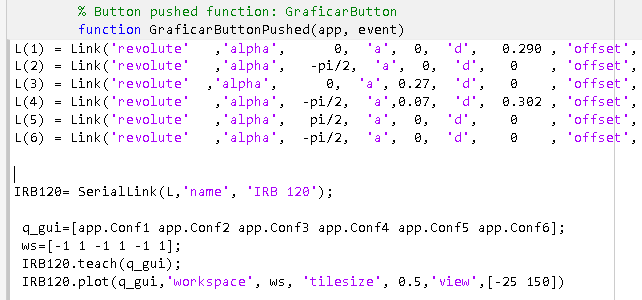

La interfaz gráfica se ve de la aiguiente manera:

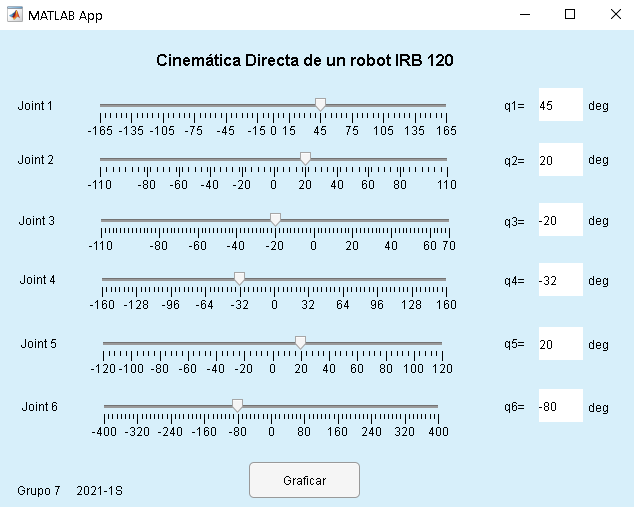

Al graficar se despliega la ventana que produce el comando teach

6. En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones. Comprobamos para las configuraciones calculadas anteriormente, deben ser ingresadas en grados decimales en los slicers.

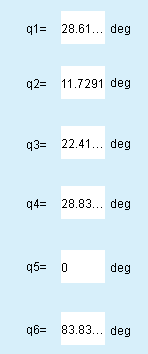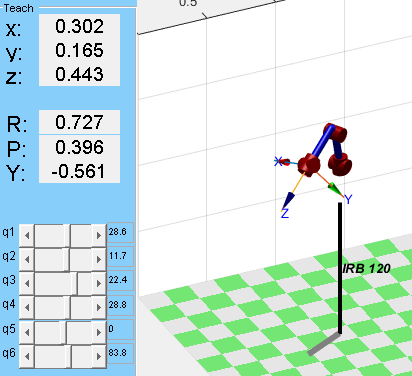

%%%%Recordando
disp(P1)

    0.3526    0.1927    0.4012



disp(O1)

    1.1416    0.6000    0.5000



%%%%Recordando
disp(P2)

    0.0280   -0.4523    0.5060



disp(O2)

    0.2509    0.2757    1.1541



%%%%Recordando
disp(P3)

    0.5720    0.0551    0.3560



disp(O3)

    0.4255   -0.0483    0.8727



%%%%Recordando
disp(P4)

    0.0576   -0.0794    0.8803



disp(O4)

    1.3218   -0.7410    0.8949



IRB120.ikine(MTH1)

ans =     0.3815    0.1781    0.5716    3.1233    0.6076  -20.5361


## Modelo Geometrico Inverso

1. Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase.

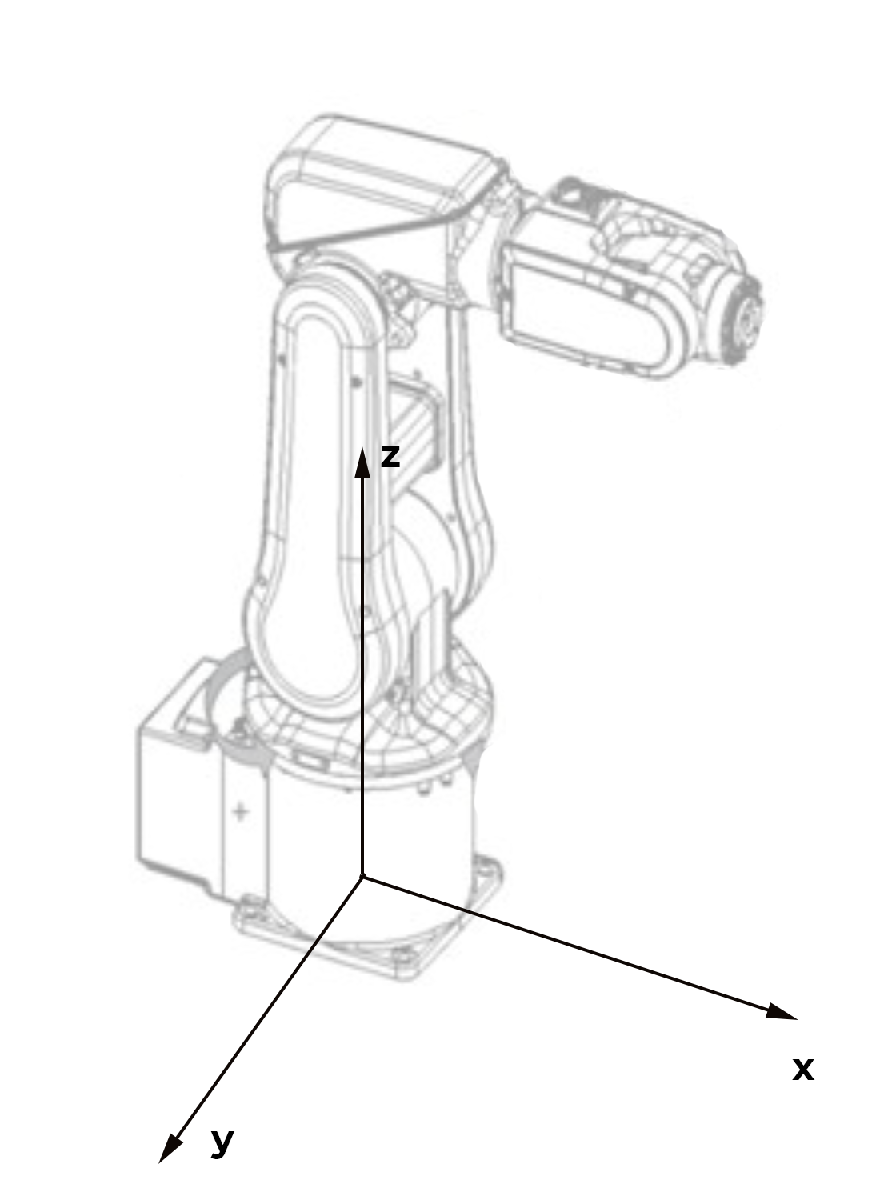

Usando como planos de referencia, los que se aprecian en la figura anterior, se realizará la cinemática inversa.

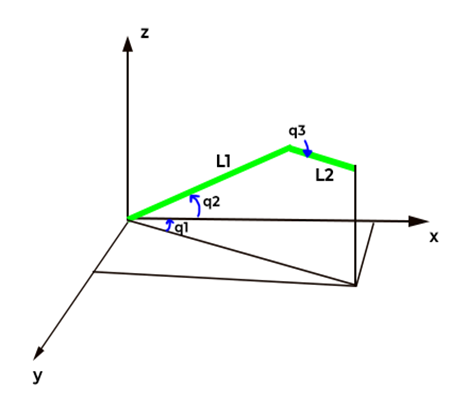

Para analizar la primera articulación, usamos el siguiente diagrama que representa una vista superior en el plano x-y.

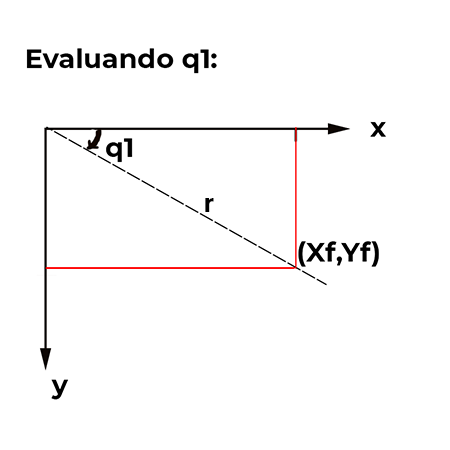


$$\textrm{q1}=\textrm{atan2}\left(y_f ,x_f \right)$$


De la misma forma, para la segunda y tercera articulación, usamos el siguiente diagrama que representa una vista lateral del robot en el plano x-z.

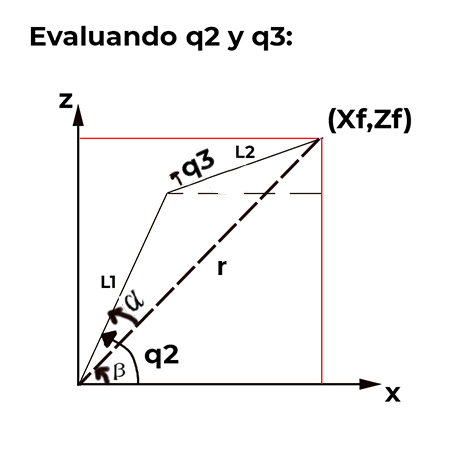

Para q3:


$$r=\sqrt{{x_f }^2 +{z_f }^2 }$$



$$\begin{array}{l}
r^2 ={L_1 }^2 +{L_2 }^2 +2L_1 L_2 \cdot \cos \left(q_3 \right)\\
\cos \left(q_3 \right)=\frac{r^2 -{L_1 }^2 -{L_2 }^2 }{2L_1 L_2 }\\
\textrm{sen}\left(q_3 \right)=\pm \sqrt{1-\cos^2 \left(q_3 \right)}\\
q_3 =\textrm{atan2}\left(\textrm{sen}q_2 ,\cos q_2 \right)
\end{array}$$


Para q2:


$$\begin{array}{l}
\beta =\textrm{atan2}\left(z_f ,x_f \right)\\
{L_2 }^2 ={L_1 }^2 +r^2 +2L_1 r\cdot \cos \left(\alpha \right)
\end{array}$$



$$\cos \left(\alpha \right)=\frac{{L_2 }^2 -{L_1 }^2 -r^2 }{2L_1 r}$$



$$\textrm{sen}\left(\alpha \right)=\pm \sqrt{1-\cos^2 \left(\alpha \right)}$$



$$\alpha =\textrm{atan2}\left(\textrm{sen}\alpha ,\cos \alpha \right)$$



$$q_2 =\alpha \pm \beta$$


Finalmente, para las articulaciones q4, q5 y q6 es necesario conocer las matrices de transformación homogénea ya que estas no se puede representar geométricamente de la misma manera que las articulaciones anteriores. Por tanto, para calcular el valor de dichas articulaciones es posible despejar alguna de dichas variables de las ecuaciones finales que se mostrarán a continuación: 


$$T_4^6 =T_3^4 \cdot T_4^5 \cdot T_5^6$$


F46 = F_4*F_5*F_6

$$F46 = \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & \frac{7}{100}\\ \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & -\sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) & \frac{151}{500}\\ -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Al obtener estos valores en la matriz general de transformación del efector final, es posible despejar alguna de estas variables, dependiendo de la orientación y posición final del manipulador.

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones. 

3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique:

-¿Cuál es la diferencia entre estas funciones?

El toolbox de Peter Corke ofrece diferentes funciones que permiten calcular la cinemática inversa de un manipulador con algunas características especiales:

- **ikine6s:** Cinemática inversa para robot de revolución de muñeca esférica de 6 ejes.

- **ikine:** Cinemática inversa mediante método numérico iterativo. 

- **ikunc:** Cinemática inversa mediante optimización.    

- **ikcon:** Cinemática inversa mediante optimización con límites de articulación. 

- **ikine_sym:** Cinemática inversa analítica 'sym' obtenida simbólicamente.

-¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

En general se pueden usar varias de estas funciones siempre y cuando se incluyan correctamente los argumentos de entrada y las limitaciones físicas del mecanismo. Para este caso, se usa la cinemática inversa general en una de las posiciones vistas en el punto anterior.

*cin_inv = IRB120.ikine(MTH);*

4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.

Para este caso, se crea un solucionador para la cinemática inversa del robot. De igual forma, se pueden incluir algunos parámetros como posición, orientación y demás particularidades del manipulador.

*ik = generalizedInverseKinematics;*

*ik.RigidBodyTree = robot;*

5. Compare los métodos.

El toolbox de Peter Corke permite calcular de diferentes maneras la cinemática inversa del manipulador, donde se requiere la matriz de transformación homogénea para que esta sea evaluada y así pueda encontrar la posición final y la orientación de la herramienta.

Para el caso del Toolbox de Matlab, es más específico ya que se debe especificar una configuración particular del robot, y no es necesario conocer dichas posiciones o configuraciones a partir de la matriz de transformación.

6. Calcule la configuración del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x, y, z, roll, pitch, yaw) que esten dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 2.

robot1 = loadrobot('abbIrb120','DataFormat','row','Gravity',[0 0 -9.81]);

%Pose 1
pose=trvec2tform([0.4,0,0.3])*axang2tform([0 1 0 pi/4]);
ik = inverseKinematics('RigidBodyTree',robot1);
weights = [1 1 1 1 1 1];
initialguess = robot1.homeConfiguration;
[configSoln1,solnInfo1] = ik('tool0',pose,weights,initialguess);
qf1 = configSoln1*180/pi

qf1 =          0   22.4438   28.0868         0   -5.5307         0



%Pose 2
pose=trvec2tform([0.25,0.15,0])*axang2tform([1 0 0 pi/2]);
ik = inverseKinematics('RigidBodyTree',robot1);
weights = [1 1 1 1 1 1];
initialguess = robot1.homeConfiguration;
[configSoln2,solnInfo2] = ik('tool0',pose,weights,initialguess);
qf2 = configSoln2*180/pi

qf2 =    40.1207   86.2127   23.6242   41.8557 -105.0400  103.0870



%Pose 3
pose=trvec2tform([0,0.1,0.25])*axang2tform([0 0 1 -pi/2]);
ik = inverseKinematics('RigidBodyTree',robot1);
weights = [1 1 1 1 1 1];
initialguess = robot1.homeConfiguration;
[configSoln3,solnInfo3] = ik('tool0',pose,weights,initialguess);
qf3 = configSoln3*180/pi

qf3 =    90.0000   17.8923   68.4646   -0.0000   93.6432  180.0000



%Pose 4
pose=trvec2tform([0.25,-0.2,0.15])*axang2tform([0 1 0 pi/4]);
ik = inverseKinematics('RigidBodyTree',robot1);
weights = [1 1 1 1 1 1];
initialguess = robot1.homeConfiguration;
[configSoln4,solnInfo4] = ik('tool0',pose,weights,initialguess);
qf4 = configSoln4*180/pi

qf4 =   -45.1309   41.2744   42.1566  -50.3926  -40.5769    7.1602


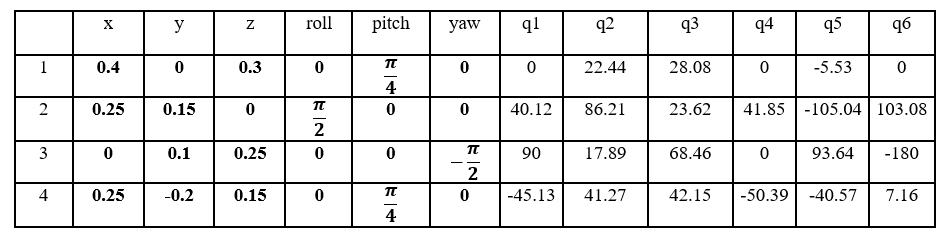

Para encontrar el valor de cada articulación, se entrenó al robot con unas coordenadas específicas (X,Y,Z) y se giró en alguno de los 3 ángulos fijos (roll,pitch,yaw) como se muestra en la tabla. De esta forma podemos obtener los resultados del siguiente punto en la configuración final del manipulador de acuerdo a sus características iniciales.

7. Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta con gráficas.

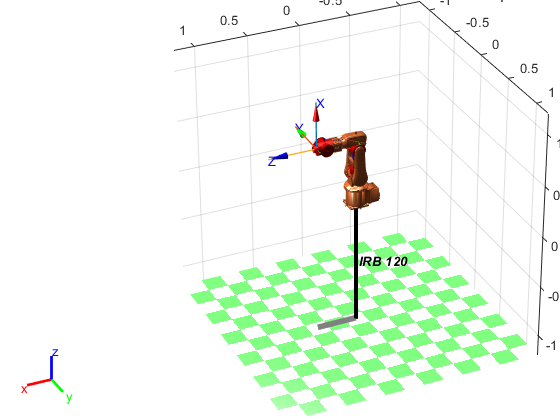

ws=[-1 1 -1 1 -1 1];
plot_options = {'workspace',ws,'scale',0.5,'view',[-25 150], 'tilesize',2,...
    'ortho', 'lightpos',[2 2 10] };

L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,  'd',   0.290 , 'offset',    0,...
    'qlim',  [-11*pi/12 11*pi/12],   'modified');
L(2) = Link('revolute'   ,'alpha',   -pi/2,  'a',  0,  'd',   0    , 'offset',   -pi/2,...
    'qlim',  [-11*pi/18 11*pi/18],   'modified');
L(3) = Link('revolute'  ,'alpha',      0,  'a', 0.27,  'd',   0    , 'offset',   0,...
    'qlim',  [-11*pi/18 7*pi/18],   'modified');
L(4) = Link('revolute'   ,'alpha',  -pi/2,  'a',0.07,  'd',  0.302 , 'offset',   0,...
    'qlim',  [-8*pi/9 8*pi/9],   'modified');
L(5) = Link('revolute'   ,'alpha',   pi/2,  'a',  0,  'd',    0    , 'offset',   0,...
    'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,  'd',    0    , 'offset',   0,...
    'qlim',  [-20*pi/9 20*pi/9],   'modified');

IRB120_1 = SerialLink(L,'name', 'IRB 120');
IRB120_1.tool=[1 0 0 0;
             0 1 0 0;
             0 0 1 0.072;
             0 0 0 1];
    
 q=[0 0 0 0 0 0];
 IRB120_1.teach(q);
 IRB120_1.plot(q,'workspace', ws, 'tilesize', 0.5,'view',[-25 150]);

- Posición 1

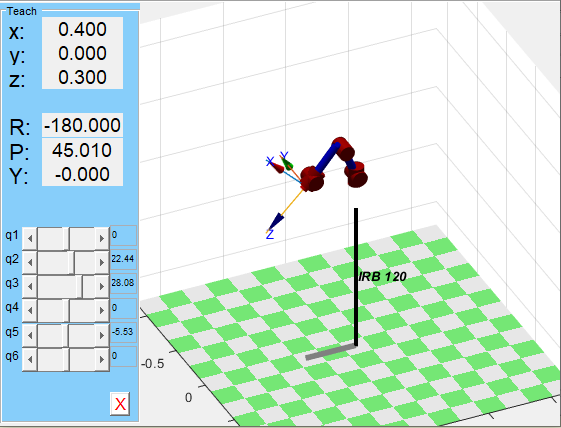

- Posición 2

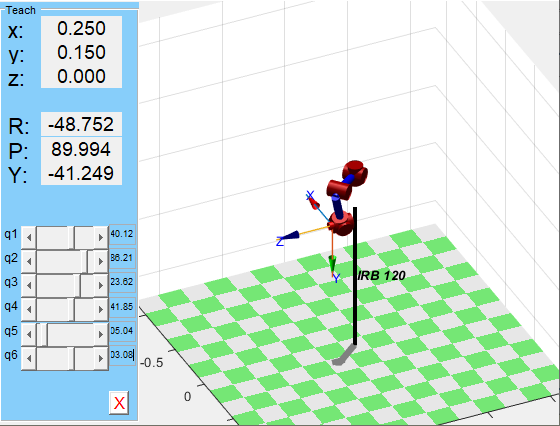

- Posición 3

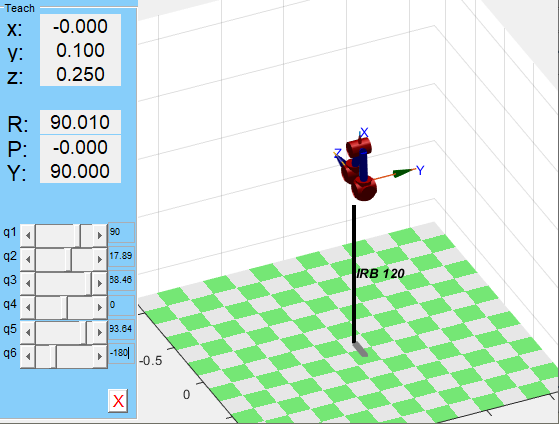

- Posición 4

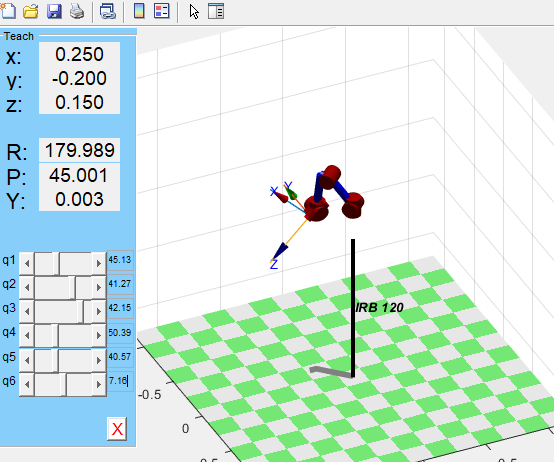

## Graficas de Velocidad Angular y Acceleración Angular


robot1 = loadrobot('abbIrb120','DataFormat','row','Gravity',[0 0 -9.81]);

pose1=trvec2tform([0.4,0.1,0.5])*axang2tform([0 1 0 pi/4]);%%3 primeros el eje y ultimo el angulo de rot

ik = inverseKinematics('RigidBodyTree',robot1);
weights = [1 1 1 1 1 1];
initialguess = robot1.homeConfiguration;
T0=getTransform(robot1,initialguess,'tool0','base')

T0 =     1.0000         0         0    0.3740
         0    1.0000         0         0
         0         0    1.0000    0.6300
         0         0         0    1.0000


[configSol1,solnInfo1] = ik('tool0',pose1,weights,initialguess);
configSol1

configSol1 =     0.2790    0.1981    0.0419   -0.3550    0.5946    0.4978


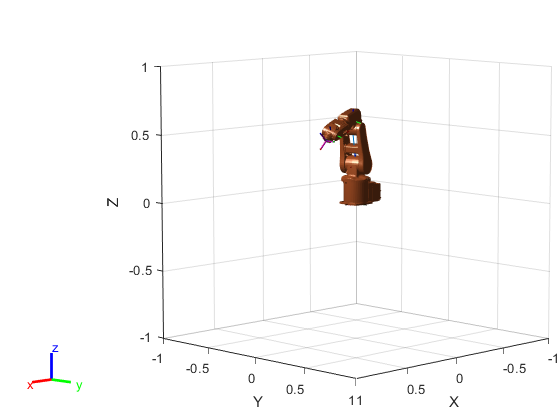

show(robot1,configSol1);

T1=getTransform(robot1,configSol1,'tool0','base')

T1 =     0.7071    0.0000    0.7071    0.4000
   -0.0000    1.0000    0.0000    0.1000
   -0.7071   -0.0000    0.7071    0.5000
         0         0         0    1.0000



pose2=trvec2tform([0.4,-0.1,0.5])*axang2tform([0 1 0 pi/4]);%%3 primeros el eje y ultimo el angulo de rot

ik = inverseKinematics('RigidBodyTree',robot1);
[configSol2,solnInfo2] = ik('tool0',pose2,weights,configSol1);
configSol2

configSol2 =    -0.2790    0.1981    0.0419    0.3550    0.5946   -0.4978


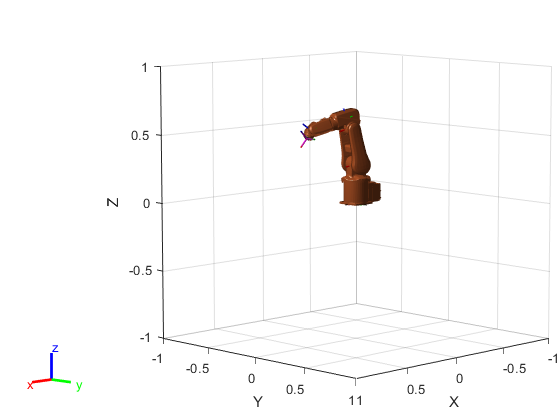

show(robot1,configSol2);

T2=getTransform(robot1,configSol2,'tool0','base')

T2 =     0.7071   -0.0000    0.7071    0.4000
    0.0000    1.0000   -0.0000   -0.1000
   -0.7071    0.0000    0.7071    0.5000
         0         0         0    1.0000



pose3=trvec2tform([0.3,-0.1,0.4])*axang2tform([0 1 0 pi/4]);%%3 primeros el eje y ultimo el angulo de rot

ik = inverseKinematics('RigidBodyTree',robot1);
[configSol3,solnInfo3] = ik('tool0',pose3,weights,configSol2);
configSol3

configSol3 =    -0.3818   -0.0820    0.6662    0.8576    0.3558   -1.1021


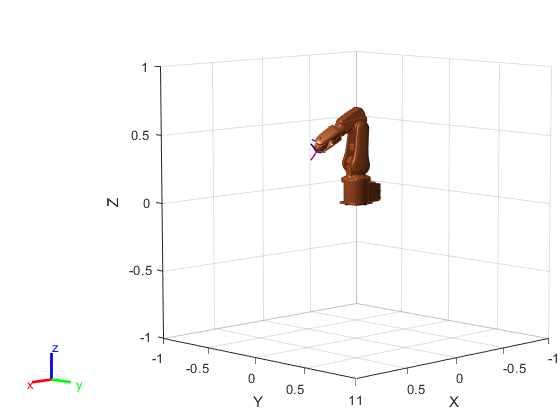

show(robot1,configSol3);

T3=getTransform(robot1,configSol3,'tool0','base')

T3 =     0.7071   -0.0000    0.7071    0.3000
    0.0000    1.0000   -0.0000   -0.1000
   -0.7071    0.0000    0.7071    0.4000
         0         0         0    1.0000



pose4=trvec2tform([0.3,0.1,0.4])*axang2tform([0 1 0 pi/4]);%%3 primeros el eje y ultimo el angulo de rot

ik = inverseKinematics('RigidBodyTree',robot1);
[configSol4,solnInfo4] = ik('tool0',pose4,weights,configSol3);
configSol4

configSol4 =     0.3818   -0.0820    0.6662    2.2840   -0.3558   -2.0395


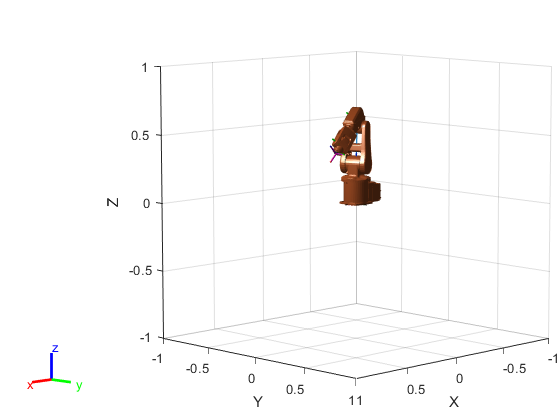

show(robot1,configSol4);

T3=getTransform(robot1,configSol4,'tool0','base')

T3 =     0.7071    0.0000    0.7071    0.3000
    0.0000    1.0000   -0.0000    0.1000
   -0.7071    0.0000    0.7071    0.4000
         0         0         0    1.0000



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t=[0:0.1:2];
[m,n] = size(t)

m = 1

n = 21

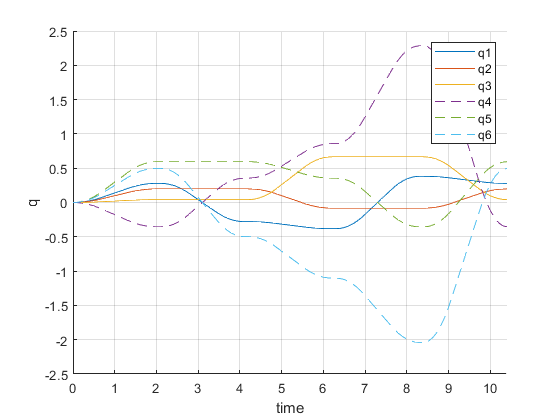

%%% de home a WayPoint 1
[qA,qdA,qddA] = mtraj(@lspb,initialguess,configSol1,n);
%%% de WayPoint 1 a WayPoint 2
[qB,qdB,qddB] = mtraj(@lspb,configSol1,configSol2,n);
%%% de WayPoint 2 a WayPoint 3
[qC,qdC,qddC] = mtraj(@lspb,configSol2,configSol3,n);
%%% de WayPoint 3 a WayPoint 4
[qD,qdD,qddD] = mtraj(@lspb,configSol3,configSol4,n);
%%% de WayPoint 4 a WayPoint 1
[qE,qdE,qddE] = mtraj(@lspb,configSol4,configSol1,n);
%%%%%trayectoria completa
tt=[0:0.1:10.4];
q=[qA;qB;qC;qD;qE];
qd=[qdA;qdB;qdC;qdD;qdE];
qdd=[qddA;qddB;qddC;qddD;qddE];
figure
qplot(tt,q)

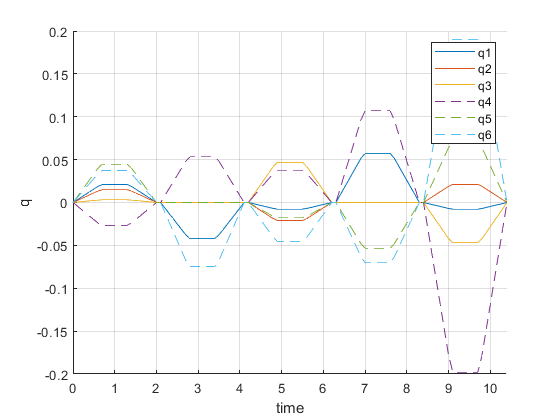

figure
qplot(tt,qd)

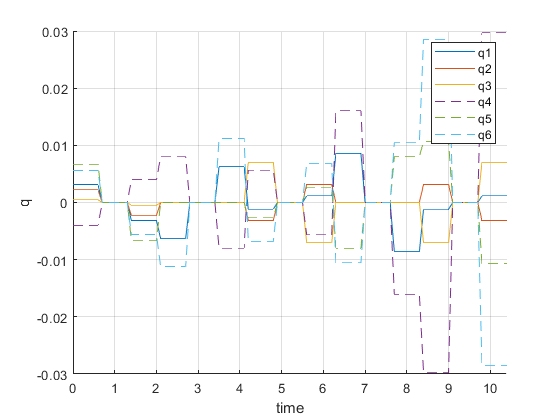

figure
qplot(tt,qdd)

## Integración: plano normal a [-1 0 1]

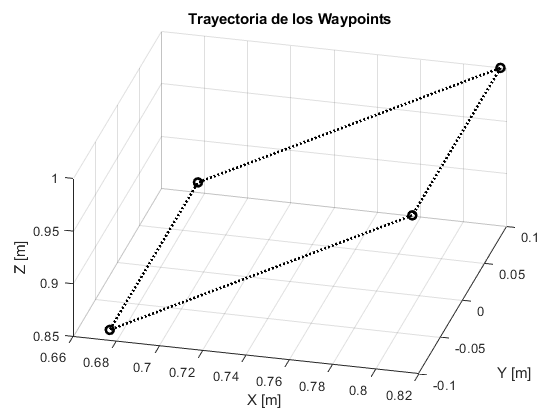

%% Parametros del robot
robot=loadrobot("abbIrb120");
eeName = 'tool0';
robot.DataFormat = 'row';

numJoints = numel(robot.homeConfiguration);
ikInitGuess = robot.homeConfiguration;

% Posicion (X Y Z)
waypoints = [0.347 0 0.630]' + ... 
            [0.47 0.1 0.37 ;
             0.47 -0.1 0.37 ;
             0.33 -0.1 0.23 ;
             0.33  0.1 0.23 ;
             0.47 0.1 0.37]';
         
% Angulos de Euler (Z Y X) relativo a home       
orientations = [0    0   0;
                0  pi/4   0; 
                0  pi/4   0;
                0  pi/4   0;
                0  pi/4   0]';   
            
% tiempo de muestreo
waypointTimes = 0:4:16;
ts = 0.2;
trajTimes = 0:ts:waypointTimes(end);

% Velocidad
waypointVels = 0.1 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;
                      1  0  0;
                      0  1  0]';

% Acceleración
waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/4;


figure, hold on
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ko:','LineWidth',2);
title('Trayectoria de los Waypoints'); 
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]');
grid on
view([14.308 43.923]);




% Define cinematica inversa
ik = inverseKinematics('RigidBodyTree',robot);
ikWeights = [1 1 1 1 1 1];
ts = 0.02;
trajTimes = 0:ts:waypointTimes(end);
% Initializa matrices
qTask = zeros(numJoints,numel(trajTimes)); 
posJoint = zeros(3,numel(trajTimes)); 



## Trayectoria de espacio de tarea

ikInitGuess = [0 0 0 0 0 0];
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;

disp('Running task space trajectory generation and evaluation...')

Running task space trajectory generation and evaluation...


tic;

% Generacion trayectoria
[posTask,velTask,accelTask] = trapveltraj(waypoints,numel(trajTimes), ...
    'AccelTime',repmat(waypointAccelTimes,[3 1]), ...
    'EndTime',repmat(diff(waypointTimes),[3 1]));

% Evaluacion trayectoria
for idx = 1:numel(trajTimes) 
    % cinematica inversa para cada punto
    tgtPose = trvec2tform(posTask(:,idx)');
    [config,info] = ik(eeName,tgtPose,ikWeights,ikInitGuess);
    ikInitGuess = config;
    qTask(:,idx) = config;
end

taskTime = toc;
disp(['Task space trajectory time : ' num2str(taskTime) ' s']);

Task space trajectory time : 935.9538 s


## Create comparison plots

% grafica de trayectoria del robot
close all
figure, hold on
plot3(posTask(1,:),posTask(2,:),posTask(3,:),'b-');
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ko','LineWidth',2);
title('Trajectory Comparison'); 
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]');
legend('Task Space Trajectory','Waypoints');
grid on
view([14.308 43.923]);
numWaypoints = size(waypoints,2);

% graficas de angulo vs tiempo de cada articulación 
for idx = 1:numJoints
    figure, hold on;
    plot(trajTimes,qTask(idx,:),'b-');
    for wIdx = 1:numWaypoints
       xline(waypointTimes(wIdx),'k--'); 
    end
    title(['Joint ' num2str(idx) ' Trajectory']); 
    xlabel('Time [s]');
    ylabel('Joint Angle [rad]');
    legend('Task Space Trajectory');
end

**Observaciones:** 

1. Forma de trabajo: Grupos de laboratorio correspondientes al proyecto de curso. 

2. Los puntos que requieran implementación de funciones deberán tener comentarios de como se utilizan y adjuntar archivos .m o .mlx. 

3. Fecha de entrega: 25/07/2021.

**Referencias** 

[1] QUT Robot Academy . Visitado en Junio de 2021 

[2] Training Mathworks, Link. Visitado en Junio de 2021 

[3] Martinez, A., Fernandez E. Leaning ROS for robotics programming, PackT Publishing. 

[4] Corke, Peter. Robotics, Vision Control. 2017 

[5] Craig, John. Introduction to Robotics: Mechanics and Control. 4 Ed. 2017